Problema 1.4

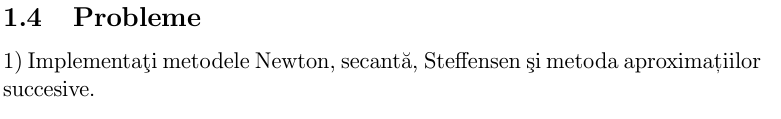

% Metoda lui Newton pentru ecuatii liniare 
f  = @(x) (cos(x) - x);
fd = @(x) (-sin(x) - 1);
x0 = 0.4;
[z, ni] = newton(f, fd, x0);
fprintf("Metoda lui Newton:");

Metoda lui Newton:

fprintf("f(x) = cos(x) - x");

f(x) = cos(x) - x

fprintf("x = %f", z);

x = 0.739085

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 3

% Metoda secantei pentru ecuatii liniare
f    = @(x) (cos(x) - x);
x1   = [0.5, 0.4];
x2   = [pi/4, pi/5];
err  = eps;
nmax = 100;

[z, ni] = secanta(f, x1, x2, err, nmax);
fprintf("Metoda secantei:");

Metoda secantei:

fprintf("f(x) = cos(x) - x");

f(x) = cos(x) - x

fprintf("x1 = %f, x2 = %f", z);

x1 = 0.797312, x2 = 0.640232

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 1

Problema 2.4

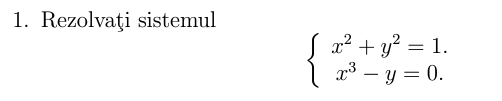

f  = @(x) [x(1)^2 + x(2)^2 - 1; x(1)^3 - x(2)];
fd = @(x) [2*x(1), 2*x(2); 3*x(1)^2, - 1];
x0 = [1; 1];

[z, ni] = newton_neliniar(f, fd, x0, 1e-9);
fprintf("Rezolvarea sistemului prin metoda lui Newton:");

Rezolvarea sistemului prin metoda lui Newton:

fprintf("x = %f, y = %f", z);

x = 0.826031, y = 0.563624

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 5

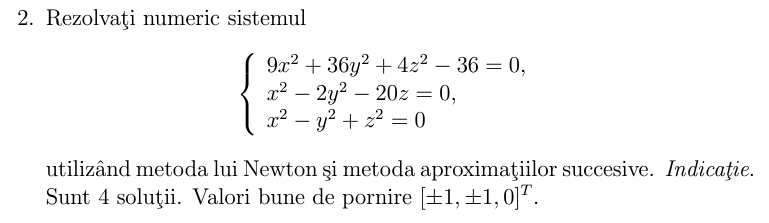

f = @(x)[9 * x(1)^2 + 36 * x(2)^2 + 4 * x(3)^2 - 36;
         x(1)^2 - 2 * x(2)^2 - 20 * x(3);
         x(1)^2 - x(2)^2 + x(3)^2];
fd = @(x)[18 * x(1) + 36 * x(2)^2 + 4 * x(3)^2, 9 * x(1)^2 + 72 * x(2) + 4 * x(3)^2, 9 * x(1)^2 + 36 * x(2)^2 + 8 * x(3);
          2 * x(1) - 2 * x(2)^2 - 20 * x(3), x(1)^2 - 4 * x(2) - 20 * x(3), x(1)^2 - 2 * x(2)^2 - 20;
          2 * x(1) - x(2)^2 + x(3)^2, x(1)^2 - 2 * x(2) + x(3)^2, x(1)^2 - x(2)^2 + 2 * x(3)];
x0 = [1, 1, 0];

% Newton:
[z, ni] = newton_neliniar(f, fd, x0, 1E-9, 100);
fprintf("Prin metoda lui Newton:");

Prin metoda lui Newton:

fprintf("x = %f, y = %f, z = %f", z);

x = 0.946667, y = 0.946667, z = -0.040000

fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 1


% Aproximări succesive:
[z, ni] = succ_aprox(f, fd, x0, 1E-9, 100);
fprintf("Prin metoda aproximărilor succesive:");

Prin metoda aproximărilor succesive:

disp(z);

    0.8936    0.8936   -0.1064
    0.8945    0.8945   -0.1055
   -0.0401   -0.0401   -1.0401



fprintf("Numărul de iterații efectuate: %d", ni);

Numărul de iterații efectuate: 92